General overview of pole locations in s-Plane

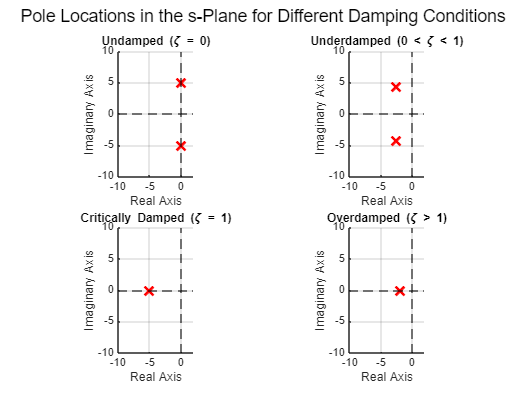

% Parameters
m = 1;                   % mass (kg)
k = 25;                  % spring constant (N/m)
b_values = [0, 5, 10, 15]; % Damping coefficients for various cases

% Natural frequency
omega_n = sqrt(k/m);

% Case labels
labels = {'Undamped (\zeta = 0)', ...
          'Underdamped (0 < \zeta < 1)', ...
          'Critically Damped (\zeta = 1)', ...
          'Overdamped (\zeta > 1)'};

% Create figure
figure;
for i = 1:4
    b = b_values(i);
    zeta = b / (2 * sqrt(k * m));  % Damping ratio
    
    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    
    % Create subplot
    subplot(2, 2, i);
    hold on; grid on; axis equal;
    xlabel('Real Axis'); ylabel('Imaginary Axis');
    title(labels{i});
    
    % Plot poles
    plot(real(s1), imag(s1), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    plot(real(s2), imag(s2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    
    % Axis limits
    xlim([-10, 2]);
    ylim([-10, 10]);
    
    % Add origin lines
    xline(0, '--k');
    yline(0, '--k');
end

sgtitle('Pole Locations in the s-Plane for Different Damping Conditions');

Pole response to change in damping coefficient

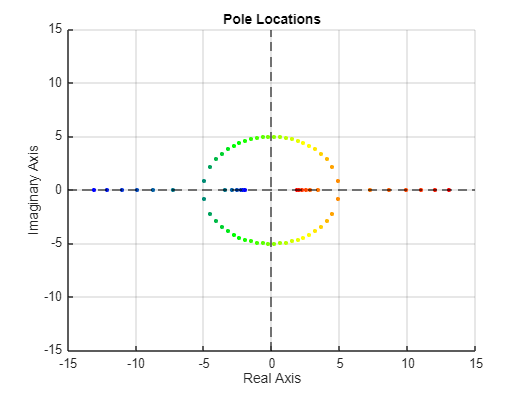

figure('Name','Fig 2');
hold on
grid on

n = 36; % Number of systems
b_values = linspace(-15,15,n); % Damping ratios from 0 to 15
color_grad = color_progression(n); % Color gradient to show pole progression

% Pole locations
for i=1:length(b_values)
    b=b_values(i);
    zeta = b / (2 * sqrt(k*m)); % Damping ratio

    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);

    % Plot poles
    plot(real(s1), imag(s1), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));
    plot(real(s2), imag(s2), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));

end

% Axis limits and guides
xlim([-15, 15]);
ylim([-15, 15]);
xline(0, '--k');
yline(0, '--k');

title('Pole Locations');
xlabel('Real Axis');
ylabel('Imaginary Axis');
hold off

Pole response to change in damping coefficient with ordered data points

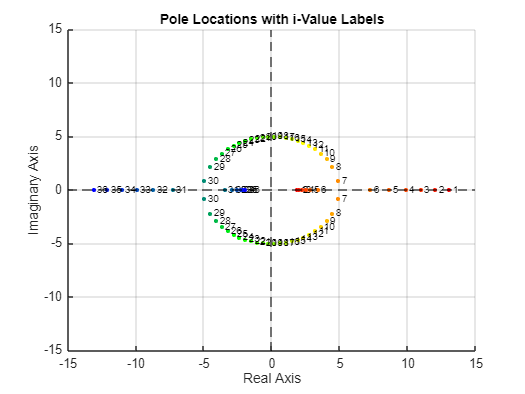

figure('Name','Fig3')
hold on
grid on
% Pole locations
for i=1:length(b_values)
    b=b_values(i);
    zeta = b / (2 * sqrt(k*m)); % Damping ratio

    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);

    % Plot poles
    plot(real(s1), imag(s1), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));
    plot(real(s2), imag(s2), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));

    % Label each pole with 'i'
    text(real(s1), imag(s1), sprintf(' %d', i), 'FontSize', 8, 'Color', 'k');
    text(real(s2), imag(s2), sprintf(' %d', i), 'FontSize', 8, 'Color', 'k');

end

% Axis limits and guides
xlim([-15, 15]);
ylim([-15, 15]);
xline(0, '--k');
yline(0, '--k');

title('Pole Locations with i-Value Labels');
xlabel('Real Axis');
ylabel('Imaginary Axis');

Duplicate of above code, with different parameters:

General overview of pole locations in s-Plane

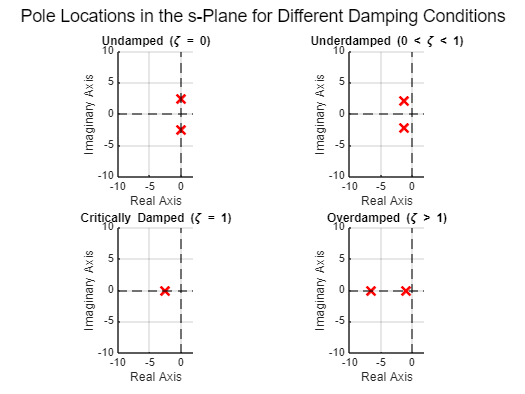

% Parameters
m = 4;                   % mass (kg)
k = 25;                  % spring constant (N/m)
b_values = [0 10 20 30]; % Damping coefficients for various cases

% Natural frequency
omega_n = sqrt(k/m);

% Case labels
labels = {'Undamped (\zeta = 0)', ...
          'Underdamped (0 < \zeta < 1)', ...
          'Critically Damped (\zeta = 1)', ...
          'Overdamped (\zeta > 1)'};

% Create figure
figure;
for i = 1:4
    b = b_values(i);
    zeta = b / (2 * sqrt(k * m));  % Damping ratio
    
    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    
    % Create subplot
    subplot(2, 2, i);
    hold on; grid on; axis equal;
    xlabel('Real Axis'); ylabel('Imaginary Axis');
    title(labels{i});
    
    % Plot poles
    plot(real(s1), imag(s1), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    plot(real(s2), imag(s2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    
    % Axis limits
    xlim([-10, 2]);
    ylim([-10, 10]);
    
    % Add origin lines
    xline(0, '--k');
    yline(0, '--k');
end

sgtitle('Pole Locations in the s-Plane for Different Damping Conditions');

Pole response to change in damping coefficient

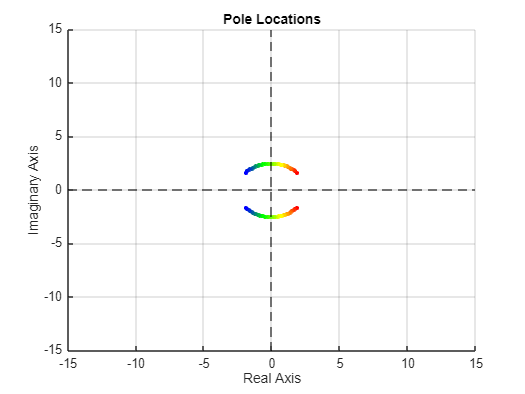

figure('Name','Fig 2');
hold on
grid on

n = 36; % Number of systems
b_values = linspace(-15,15,n); % Damping ratios from 0 to 15
color_grad = color_progression(n); % Color gradient to show pole progression

% Pole locations
for i=1:length(b_values)
    b=b_values(i);
    zeta = b / (2 * sqrt(k*m)); % Damping ratio

    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);

    % Plot poles
    plot(real(s1), imag(s1), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));
    plot(real(s2), imag(s2), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));

end

% Axis limits and guides
xlim([-15, 15]);
ylim([-15, 15]);
xline(0, '--k');
yline(0, '--k');

title('Pole Locations');
xlabel('Real Axis');
ylabel('Imaginary Axis');
hold off

Pole response to change in damping coefficient with ordered data points

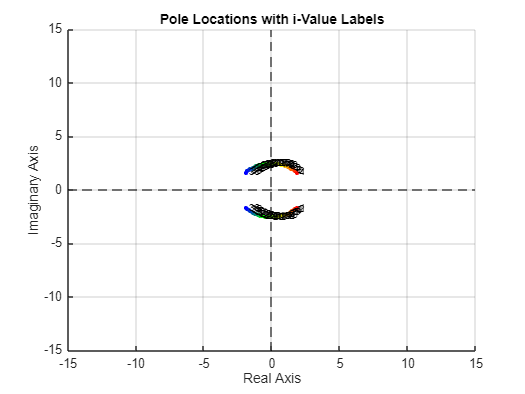

figure('Name','Fig3')
hold on
grid on
% Pole locations
for i=1:length(b_values)
    b=b_values(i);
    zeta = b / (2 * sqrt(k*m)); % Damping ratio

    % Compute characteristic polynomial coefficients: ms^2 + bs + k
    a = m;
    coeff_b = b;
    coeff_c = k;
    
    % Solve for poles using quadratic formula
    s1 = (-coeff_b + sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);
    s2 = (-coeff_b - sqrt(coeff_b^2 - 4*a*coeff_c)) / (2*a);

    % Plot poles
    plot(real(s1), imag(s1), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));
    plot(real(s2), imag(s2), 'r.', 'MarkerSize', 10, 'LineWidth', 2,'Color',color_grad(:,i));

    % Label each pole with 'i'
    text(real(s1), imag(s1), sprintf(' %d', i), 'FontSize', 8, 'Color', 'k');
    text(real(s2), imag(s2), sprintf(' %d', i), 'FontSize', 8, 'Color', 'k');

end

% Axis limits and guides
xlim([-15, 15]);
ylim([-15, 15]);
xline(0, '--k');
yline(0, '--k');

title('Pole Locations with i-Value Labels');
xlabel('Real Axis');
ylabel('Imaginary Axis');